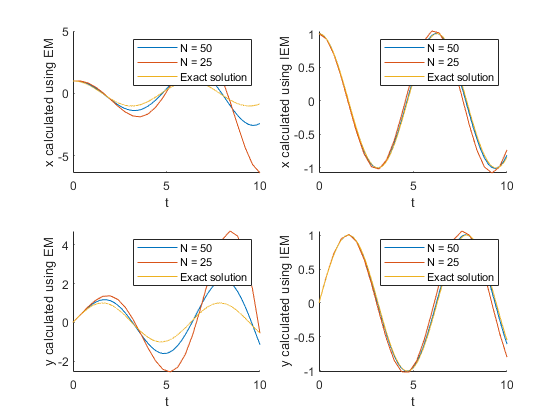

e = 0;
f = -1;
g = 1;
h = 0;
x_0 = 1;
y_0 = 0;

% More accurate graphs
T = 10;
N = 50;
dt = T/N;
t = 0 : dt : T;
[x, y] = EMsolver(e, f, g, h, x_0, y_0, T, N);
[X, Y] = IEMsolver(e, f, g, h, x_0, y_0, T, N);

% Less accurate graphs
N = 25;
dt = T/N;
tbad = 0 : dt : T;
[xbad, ybad] = EMsolver(e, f, g, h, x_0, y_0, T, N);
[Xbad, Ybad] = IEMsolver(e, f, g, h, x_0, y_0, T, N);

% Exact graphs
N = 10000;
dt = T/N;
tex = 0 : dt : T;
xex = cos(tex);
yex = sin(tex);

% Plotting
subplot(2,2,1)
hold on
plot(t, x)
plot(tbad, xbad)
plot(tex, xex)
xlabel('t')
ylabel('x calculated using EM')
legend('N = 50', 'N = 25', 'Exact solution')
hold off

subplot(2,2,2)
hold on
plot(t, X)
plot(tbad, Xbad)
plot(tex, xex)
xlabel('t')
ylabel('x calculated using IEM')
legend('N = 50', 'N = 25', 'Exact solution')
hold off

subplot(2,2,3)
hold on
plot(t, y)
plot(tbad, ybad)
plot(tex, yex)
xlabel('t')
ylabel('y calculated using EM')
legend('N = 50', 'N = 25', 'Exact solution')
hold off

subplot(2,2,4)
hold on
plot(t, Y)
plot(tbad, Ybad)
plot(tex, yex)
xlabel('t')
ylabel('y calculated using IEM')
legend('N = 50', 'N = 25', 'Exact solution')
hold off


% Q1: # of time steps needed for Euler's method to be close match to exact
% solution is around 150

% Q2: # of time steps needed for improved Euler's method to be close match to exact
% solution is around 25


function [x, y] = EMsolver(e, f, g, h, x_0, y_0, T, N)
    dt = T/N;
    t = 0 : dt : T;
    SOL = NaN(2, length(t));
    SOL(:,1) = [x_0 y_0]';
    A = [e f ; g h];
    for i = 2:length(t)
        SOL(:,i) = SOL(:,i-1) + A*SOL(:,i-1).*dt;
    end
    x = SOL(1,:);
    y = SOL(2,:);
end


function [x, y] = IEMsolver(e, f, g, h, x_0, y_0, T, N)
    dt = T/N;
    t = 0 : dt : T;
    SOL = NaN(2, length(t));
    SOL(:,1) = [x_0 y_0]';
    A = [e f ; g h];
    for i = 2:length(t)
        m_prev = A*SOL(:,i-1);
        sol_cur = SOL(:,i-1) + A*SOL(:,i-1).*dt;
        m_cur = A*sol_cur;
        S = (m_prev + m_cur) ./ 2;
        SOL(:,i) = SOL(:,i-1) + S.*dt;
    end
    x = SOL(1,:);
    y = SOL(2,:);
 end
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    